## **Modelowanie Systemów Dynamicznych**

# **Identyfikacja**

## Jan Rosa 410269 AiR

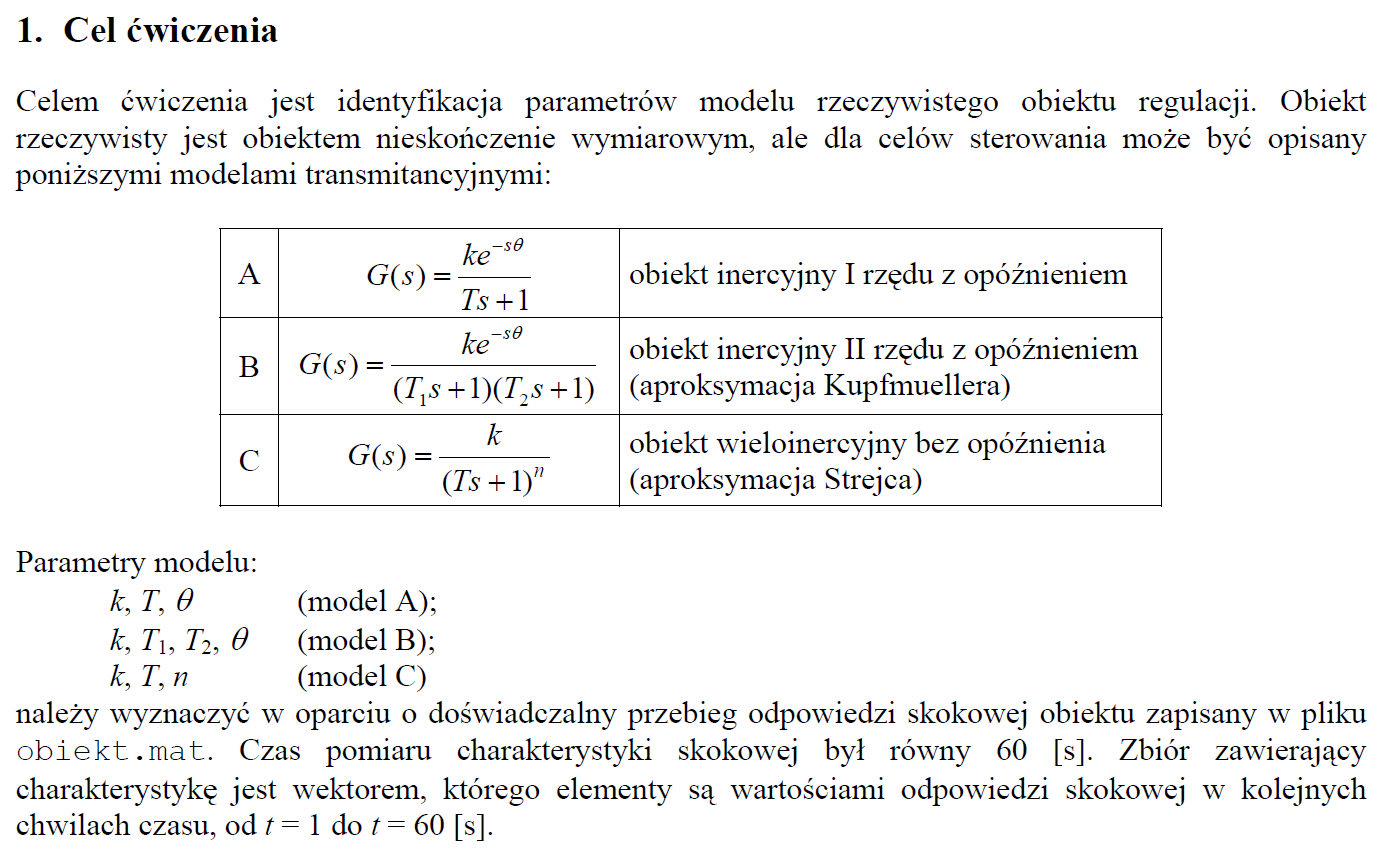

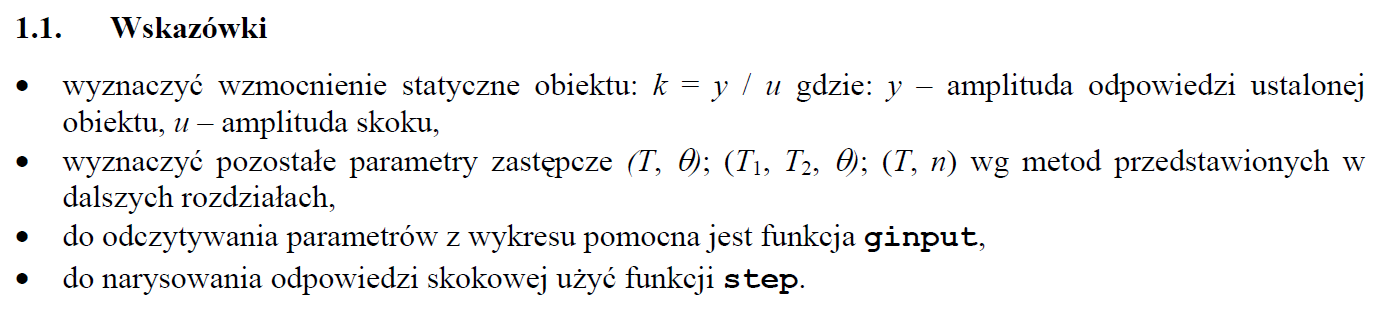

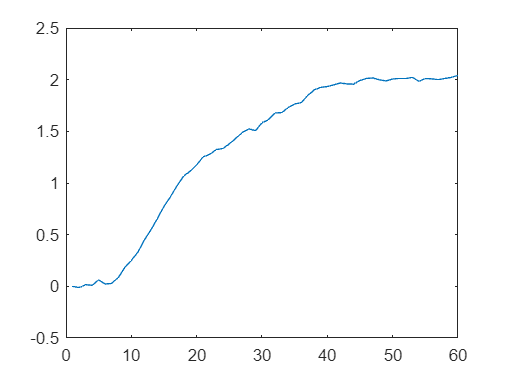

load obiekt.mat;
y_rzecz = y;
t = 1:60;
figure
plot(t,y);

### Obiekt A

#### Metoda 2.1

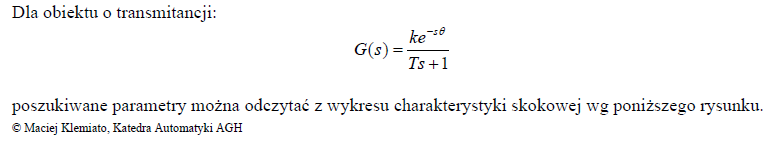

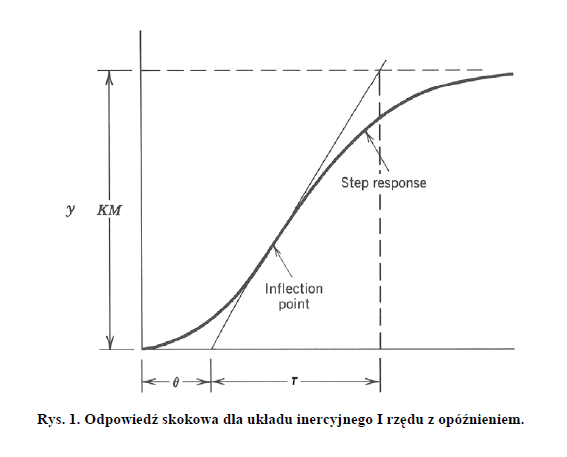

k = 2;
theta = 8.5;
T = 12;
obiektA21 = tf([0 k], [T 1], 'Inputdelay', theta)

obiektA21 =
 
                   2
  exp(-8.5*s) * --------
                12 s + 1
 
Continuous-time transfer function.



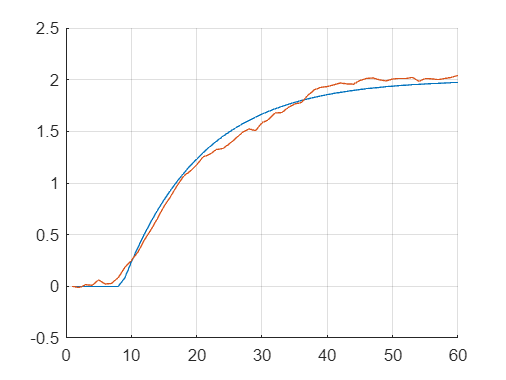

[yA1, tA1] = step(obiektA21, t);
figure
hold on; grid on;
plot(tA1, yA1, t, y)
hold off;

#### Metoda 2.4

K0 = 1; T0 = 5; theta = 3;
[par, blad] = fminsearch('identA',[K0,T0,theta])

par =     2.1516   15.8017    7.8955


blad = 0.0015


obiektA24 = tf([0 par(1)], [par(2) 1], 'Inputdelay', par(3))

obiektA24 =
 
                  2.152
  exp(-7.9*s) * ----------
                15.8 s + 1
 
Continuous-time transfer function.



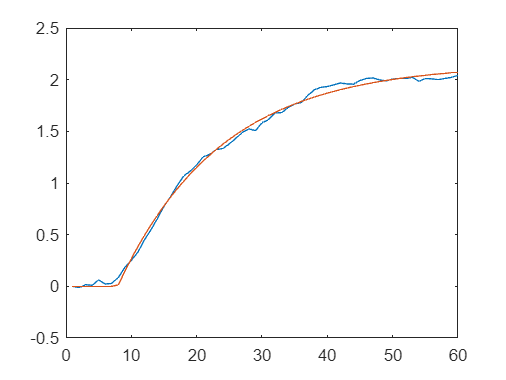

y = step(obiektA24, t);
figure
plot(t, y_rzecz, t, y)

### Obiekt B

#### Metoda 2.3

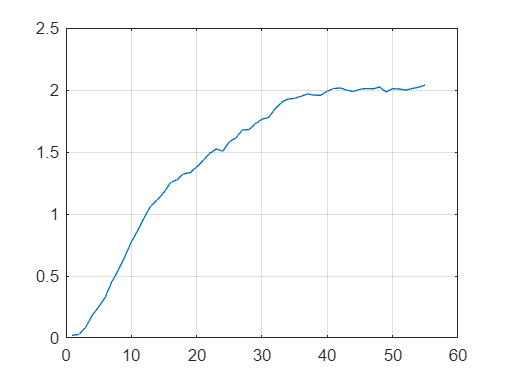

thetaB23 = 6;
k = 2;
yB23 = y_rzecz(thetaB23:end);
figure
plot(yB23)
grid on;


t73 = 20;
Tsum = t73/1.3;
t2 = Tsum/2

t2 = 7.6923

y1 = 0.62;
y1/k

ans = 0.3100

T1 = Tsum * 0.72;
T2 = Tsum - T1;

obiektB23 = tf([0 0 k],[T1*T2 T1+T2 1], 'Inputdelay', thetaB23)

obiektB23 =
 
                         2
  exp(-6*s) * -----------------------
              47.72 s^2 + 15.38 s + 1
 
Continuous-time transfer function.



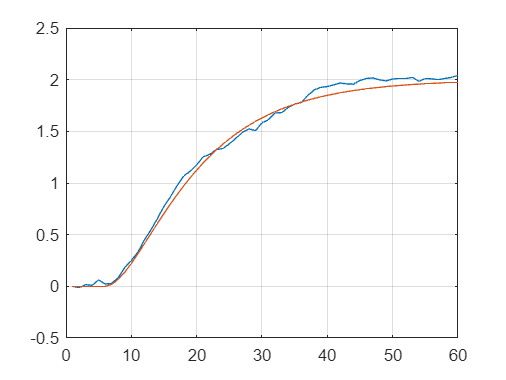

[yB23, tB23] = step(obiektB23, t);
figure
plot(t, y_rzecz, tB23, yB23); grid on;

#### Metoda 2.4

K0 = 1; T1 = 5; T2 = 5; theta = 3;
[par, blad] = fminsearch('identB',[K0,T1,T2,theta])

par =     2.1292    2.0541   14.8404    6.2836


blad = 0.0013


obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', par(4))

obiektA24 =
 
                          2.129
  exp(-6.28*s) * -----------------------
                 30.48 s^2 + 16.89 s + 1
 
Continuous-time transfer function.



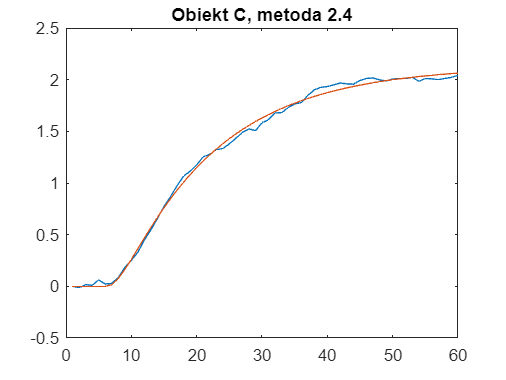

y = step(obiektA24, t);
figure
plot(t, y_rzecz, t, y)
title("Obiekt C, metoda 2.4")

### Obiekt C

#### Metoda 2.4

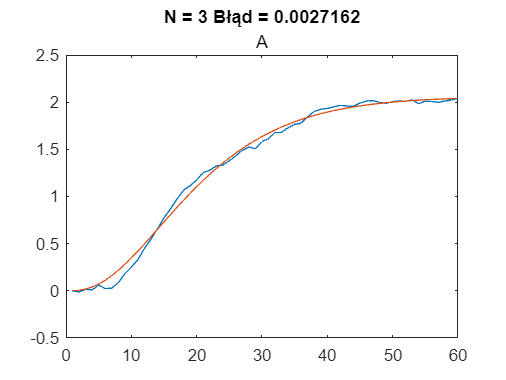

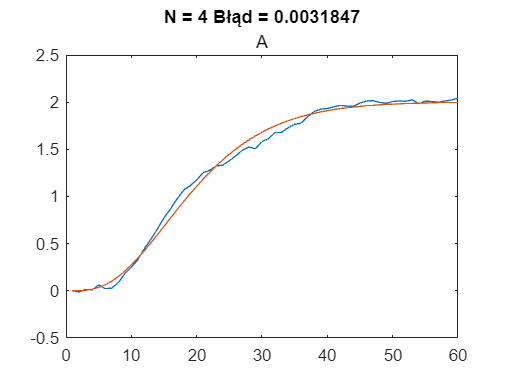

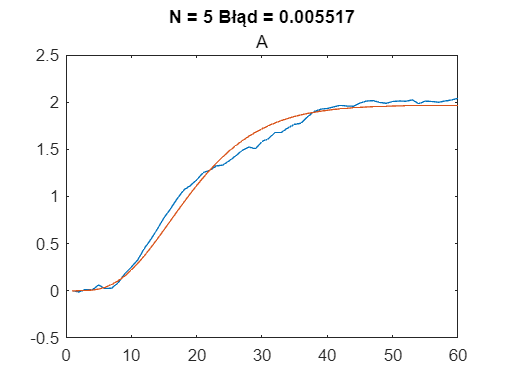

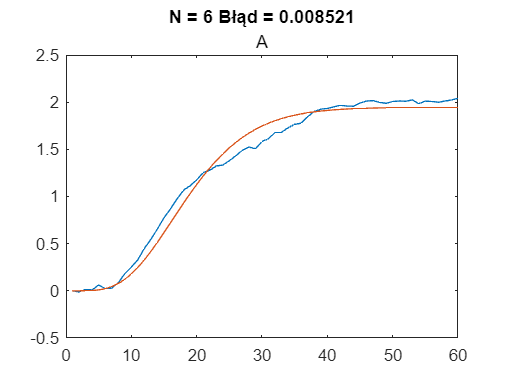

load obiekt;
N = 3:6;
K0 = 2;
T0 = 10;
global n;
for i = N
    n=i;
    [par, blad] = fminsearch('identC',[K0,T0]);
    s = tf('s');
    obiekt =  par(1) * (1/(par(2)*s + 1))^i;
    y_sym = step(obiekt, t);
    figure
    blod = num2str(blad);
    plot(t, y_rzecz, t, y_sym);
    title("N = " + num2str(i) + " Błąd = " + blod, "A");
end